## Data sampling for ID

### trim data

start_time = duration('00:03:35.148000');
end_time = duration('00:03:35.152000');
Ts = seconds(end_time -start_time)

Ts = 0.0040

% Create a timerange object
ts_range = timerange(start_time, end_time);

% Index both pitch_in and elevator using the rows subscript
elevator_trim = pitch_in.pitch_in(ts_range,:) - elevator.elevator(ts_range,:)

elevator_trim = 0

throttle_trim = throttle_in.throttle_in(ts_range,:) - throttle.throttle(ts_range,:)

throttle_trim = 0.2347

airspeed_trim = ind_airspeed.indicated_airspeed(ts_range,:)

airspeed_trim = single
13.7724

alt_trim = alt.alt(ts_range,:)

alt_trim = single
556.9732

pitch_rate_trim = q.q(ts_range,:)

pitch_rate_trim = 0.0016

alpha_trim = alpha.alpha(ts_range,:)

alpha_trim = single
0.7386

### step input

t_start = duration('00:03:35.096000');
t_end_s = duration('00:03:45.068000');
t_end_p = duration('00:03:55.040000');

% sampling the short period inputs - 5 secs
% Create a timerange object
ts_range = timerange(t_start, t_end_s);
throttle_s_step = throttle_in.throttle_in(ts_range,:) - throttle_trim;
elevator_s_step = pitch_in.pitch_in(ts_range,:) - elevator_trim;
q_s_step = q.q(ts_range,:); 
aoa_s_step = alpha.alpha(ts_range,:);

%smapling phugoid inputs - atleast 10 secs
% Create a timerange object
ts_range = timerange(t_start, t_end_p);
throttle_p_step = throttle_in.throttle_in(ts_range,:) - throttle_trim;
elevator_p_step = pitch_in.pitch_in(ts_range,:) - elevator_trim;
vel_p_step = ind_airspeed.indicated_airspeed(ts_range,:); 
alt_p_step = alt.alt(ts_range,:);

### doublet input

t_start = duration('00:04:08.832000');
t_end_s = duration('00:04:15.200000');
t_end_p = duration('00:04:24.748000');
% sampling the short period inputs - 5 secs
% Create a timerange object
ts_range = timerange(t_start, t_end_s);
throttle_s_doublet = throttle_in.throttle_in(ts_range,:) - throttle_trim;
elevator_s_doublet = pitch_in.pitch_in(ts_range,:) - elevator_trim;
q_s_doublet = q.q(ts_range,:); 
aoa_s_doublet = alpha.alpha(ts_range,:);

%smapling phugoid inputs - atleast 10 secs
% Create a timerange object
ts_range = timerange(t_start, t_end_p);
throttle_p_doublet = throttle_in.throttle_in(ts_range,:) - throttle_trim;
elevator_p_doublet = pitch_in.pitch_in(ts_range,:) - elevator_trim;
vel_p_doublet = ind_airspeed.indicated_airspeed(ts_range,:); 
alt_p_doublet = alt.alt(ts_range,:);

### sine sweep input

t_start = duration('00:04:41.088000');
t_end_s = duration('00:05:01.032000');
t_end_p = duration('00:05:01.032000');
% sampling the short period inputs - 5 secs
% Create a timerange object
ts_range = timerange(t_start, t_end_s);
throttle_s_sine = throttle_in.throttle_in(ts_range,:) - throttle_trim;
elevator_s_sine = pitch_in.pitch_in(ts_range,:) - elevator_trim;
q_s_sine = q.q(ts_range,:); 
aoa_s_sine = alpha.alpha(ts_range,:);

%smapling phugoid inputs - atleast 10 secs
% Create a timerange object
ts_range = timerange(t_start, t_end_p);
throttle_p_sine = throttle_in.throttle_in(ts_range,:) - throttle_trim;
elevator_p_sine = pitch_in.pitch_in(ts_range,:) - elevator_trim;
vel_p_sine = ind_airspeed.indicated_airspeed(ts_range,:); 
alt_p_sine = alt.alt(ts_range,:);

## System ID script - step

iodelay = 0;
u1 = throttle_s_step;
u2 = elevator_s_step;
u3 = throttle_p_step;
u4 = elevator_p_step;
airspeed_trim = vel_p_step(1,1);
alt_trim = alt_p_step(1,1);
pitch_rate_trim = q_s_step(1,1);
alpha_trim = aoa_s_step(1,1);
y3 = q_s_step - pitch_rate_trim;
y1 = double(vel_p_step - airspeed_trim);
y4 = double(aoa_s_step - alpha_trim);
y5 = double(alt_p_step - alt_trim);

### MIMO identification - short period mode

u = [u2];
y = [y3];
np = [2];%[3 3; 2 2];
nz = [1]%[1 1; 2 2];

nz = 1

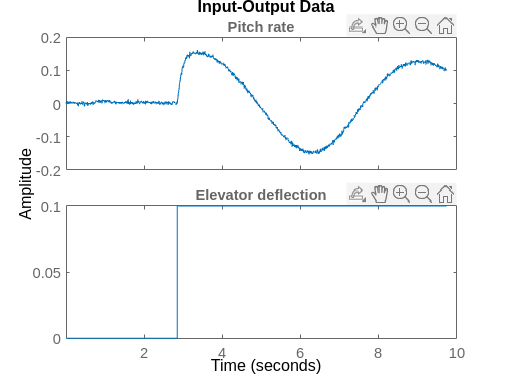

data = iddata(y,u,Ts);
set(data,'InputName',{'Elevator deflection'},'OutputName',{'Pitch rate'})
plot(data)

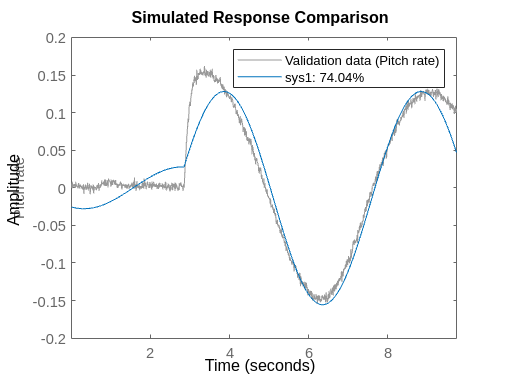

sys1= tfest(data,np,nz,iodelay);
compare(data,sys1)

### MIMO identification - Phugoid mode

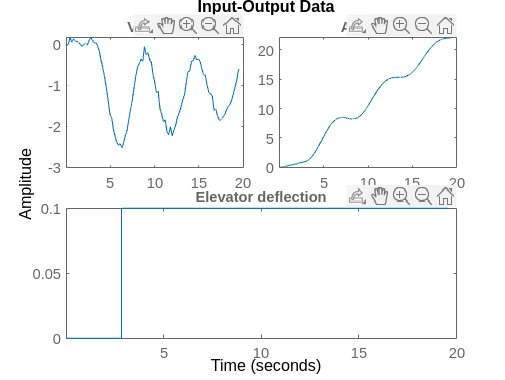

u = [u4];
y = [y1 y5];
np = [2;2];%[3 2; 3 3];
nz = [1;1];%[1 1; 2 2];
data = iddata(y,u,Ts);
set(data,'InputName',{'Elevator deflection'},'OutputName',{'Velocity', 'Altitude'});
plot(data)

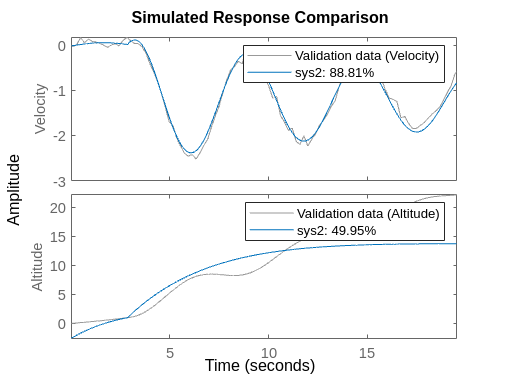

sys2= tfest(data,np,nz,iodelay);
compare(data,sys2)

### system identified

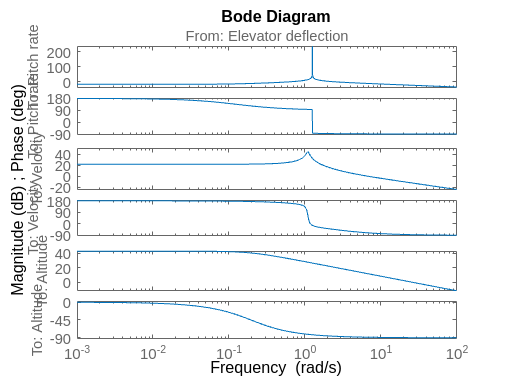

G1 = tf([sys1; sys2]);  %Inputs-Throttle, evelator & outputs-Pitchrate, aoa, velocity, height
bode(G1)

## System ID script - doublet

iodelay = 0;
u1 = throttle_s_doublet-0.05;
u2 = elevator_s_doublet;
u3 = throttle_p_doublet-0.05;
u4 = elevator_p_doublet;
airspeed_trim = vel_p_doublet(1,1);
alt_trim = alt_p_doublet(1,1);
pitch_rate_trim = q_s_doublet(1,1);
alpha_trim = aoa_s_doublet(1,1);
y1 = double(vel_p_doublet - airspeed_trim);
y3 = q_s_doublet - pitch_rate_trim;
y4 = double(aoa_s_doublet - alpha_trim);
y5 = double(alt_p_doublet - alt_trim);

### MIMO identification - short period mode

u = [u2];
y = [y3];
np = [2];%[3 3; 2 2];
nz = [1]%[1 1; 2 2];

nz = 1

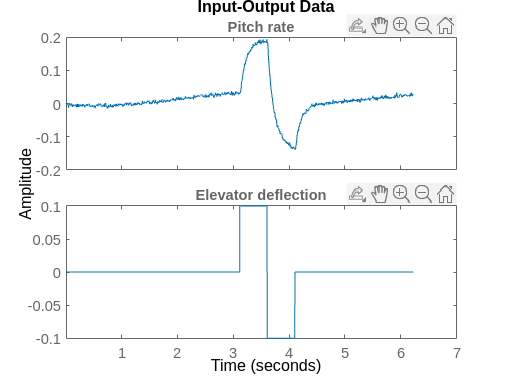

data = iddata(y,u,Ts);
set(data,'InputName',{'Elevator deflection'},'OutputName',{'Pitch rate'})
plot(data)

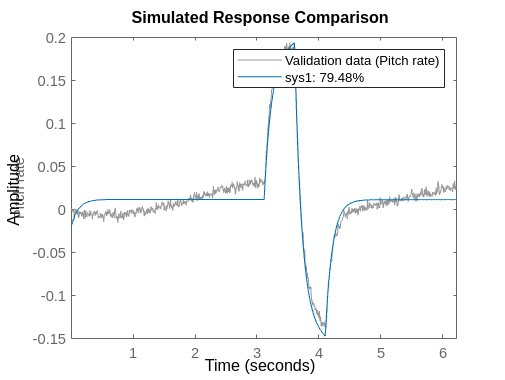

sys1= tfest(data,np,nz,iodelay);
compare(data,sys1)

### MIMO identification - Phugoid mode

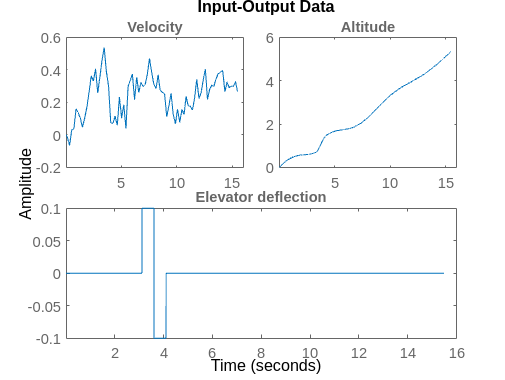

u = [u4];
y = [y1 y5];
np = [2;2];%[3 2; 3 3];
nz = [1;1];%[1 1; 2 2];
data = iddata(y,u,Ts);
set(data,'InputName',{'Elevator deflection'},'OutputName',{'Velocity', 'Altitude'});
plot(data)

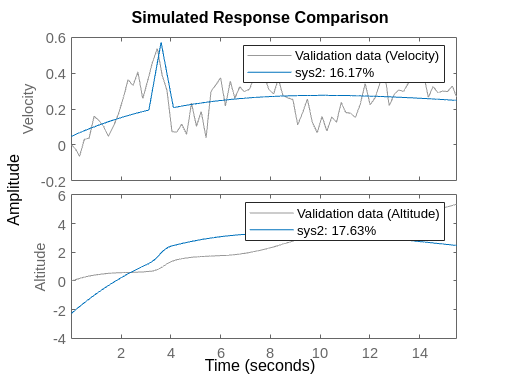

sys2= tfest(data,np,nz,iodelay);
compare(data,sys2)

### system identified

G2_e = tf([sys1; sys2])  %Inputs-Throttle, evelator & outputs-Pitchrate, aoa, velocity, height

G2_e =
 
  From input "Elevator deflection" to output...
                     14.86 s + 3.881
   Pitch rate:  -------------------------
                s^2 + 8.846 s + 3.508e-11
 
                  7.532 s + 0.8488
   Velocity:  -------------------------
              s^2 + 0.1744 s + 0.009645
 
                  1.661 s + 27.46
   Altitude:  ------------------------
              s^2 + 0.2174 s + 0.01848
 
Continuous-time transfer function.



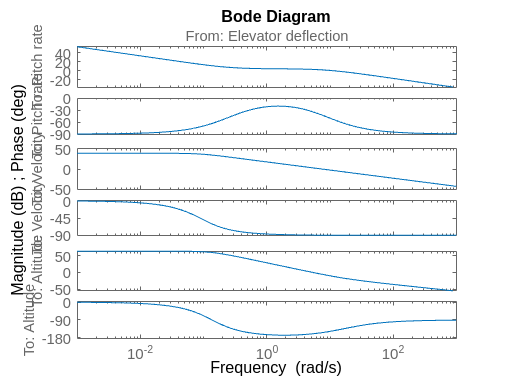

bode(G2_e)

## System ID script - sine sweep

iodelay = 0;
u1 = throttle_s_sine;
u2 = elevator_s_sine;
u3 = throttle_p_sine;
u4 = elevator_p_sine;
airspeed_trim = vel_p_sine(1,1);
alt_trim = alt_p_sine(1,1);
pitch_rate_trim = q_s_sine(1,1);
alpha_trim = aoa_s_sine(1,1);
y1 = double(vel_p_sine - airspeed_trim);
y3 = q_s_sine - pitch_rate_trim;
y4 = double(aoa_s_sine - alpha_trim);
y5 = double(alt_p_sine - alt_trim);

### MIMO identification - short period mode

u = [u2];
y = [y3];
np = [2];%[3 3; 2 2];
nz = [1]%[1 1; 2 2];

nz = 1

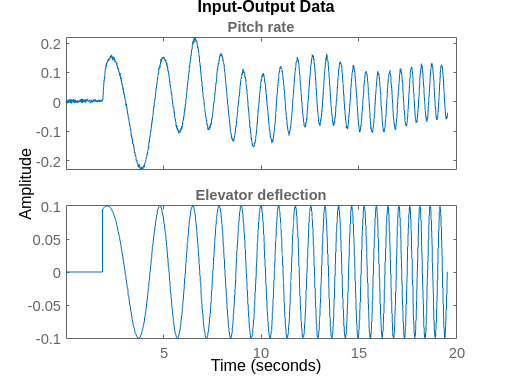

data = iddata(y,u,Ts);
set(data,'InputName',{'Elevator deflection'},'OutputName',{'Pitch rate'})
plot(data)

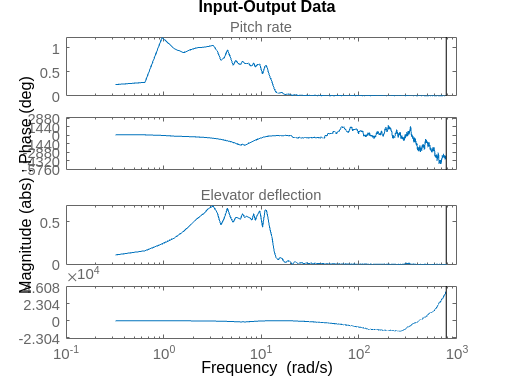

data = fft(data);
set(data,'InputName',{'Elevator deflection'},'OutputName',{'Pitch rate'})
plot(data)

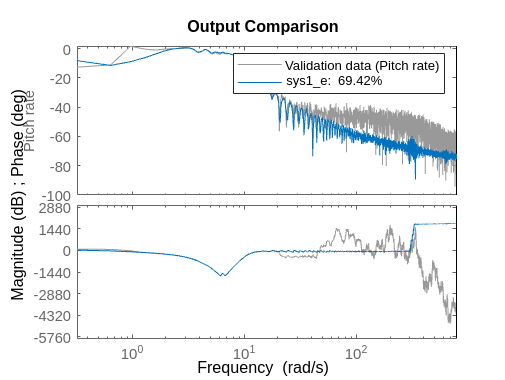

sys1_e= tfest(data,np,nz,iodelay);
compare(data,sys1_e)

### MIMO identification - Phugoid mode

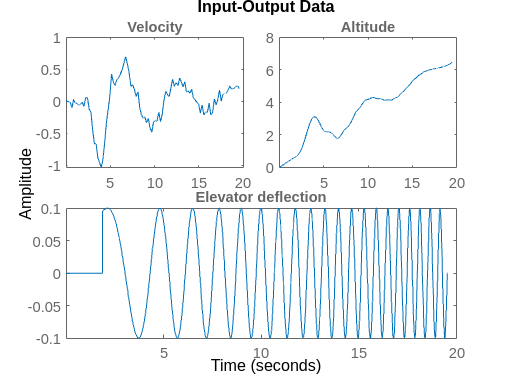

u = [u4];
y = [y1 y5];
np = [2;2];%[3 2; 3 3];
nz = [1;1];%[1 1; 2 2];
data = iddata(y,u,Ts);
set(data,'InputName',{'Elevator deflection'},'OutputName',{'Velocity', 'Altitude'})
plot(data)

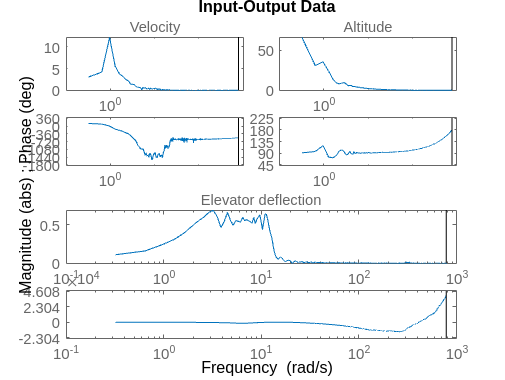

data = fft(data);
set(data,'InputName',{'Elevator deflection'},'OutputName',{'Velocity', 'Altitude'})
plot(data)

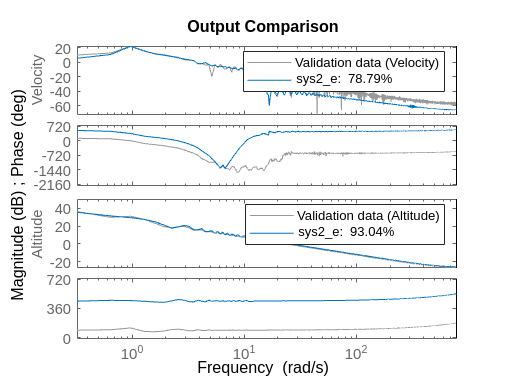

sys2_e= tfest(data,np,nz,iodelay);
compare(data,sys2_e)

### system identified

G3_e = tf([sys1_e; sys2_e])  %Inputs-Throttle, evelator & outputs-Pitchrate, aoa, velocity, height

G3_e =
 
  From input "Elevator deflection" to output...
                  12.31 s - 3.761
   Pitch rate:  --------------------
                s^2 + 6.719 s - 1.15
 
                 5.012 s - 12.95
   Velocity:  ----------------------
              s^2 + 0.2334 s + 1.019
 
                  -4.913 s + 33.15
   Altitude:  ------------------------
              s^2 + 0.9224 s - 0.06914
 
Continuous-time transfer function.



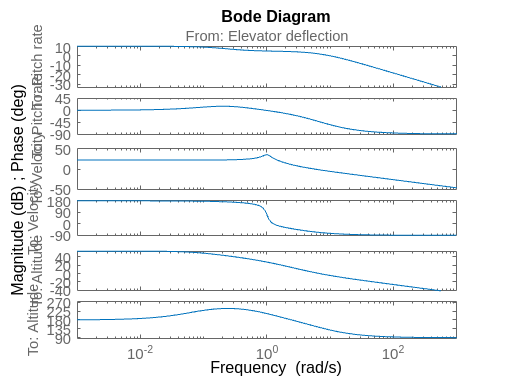

bode(G3_e)